Trova gli eigenvalue ed eigenvectors

syms a [2 1 1] real;
A=simplify(2/norm(a)^2*a*a' - eye(numel(a)))

$$A = \left(\begin{array}{cc} \frac{{a_{1}}^{2}-{a_{2}}^{2}}{{a_{1}}^{2}+{a_{2}}^{2}} & \frac{2\,a_{1}\,a_{2}}{{a_{1}}^{2}+{a_{2}}^{2}}\\ \frac{2\,a_{1}\,a_{2}}{{a_{1}}^{2}+{a_{2}}^{2}} & -\frac{{a_{1}}^{2}-{a_{2}}^{2}}{{a_{1}}^{2}+{a_{2}}^{2}} \end{array}\right)$$

p=simplify(charpoly(A))

$$p = \left(\begin{array}{ccc} 1 & 0 & -1 \end{array}\right)$$

r=roots(p)

$$r = \left(\begin{array}{c} -1.0\\ 1.0 \end{array}\right)$$

disp(r)

$$\left(\begin{array}{c} -1.0\\ 1.0 \end{array}\right)$$


%----------------------------------

syms a1 a2 a3 real;
a=[a1 a2 a3]';
A=simplify(2/norm(a)^2*a*a' - eye(numel(a)))

$$A = \begin{array}{l} \left(\begin{array}{ccc} -\frac{-{a_{1}}^{2}+{a_{2}}^{2}+{a_{3}}^{2}}{\sigma_{4}} & \sigma_{3} & \sigma_{2}\\ \sigma_{3} & -\frac{{a_{1}}^{2}-{a_{2}}^{2}+{a_{3}}^{2}}{\sigma_{4}} & \sigma_{1}\\ \sigma_{2} & \sigma_{1} & -\frac{{a_{1}}^{2}+{a_{2}}^{2}-{a_{3}}^{2}}{\sigma_{4}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,a_{2}\,a_{3}}{\sigma_{4}}\\ \sigma_{2}=\frac{2\,a_{1}\,a_{3}}{\sigma_{4}}\\ \sigma_{3}=\frac{2\,a_{1}\,a_{2}}{\sigma_{4}}\\ \sigma_{4}={a_{1}}^{2}+{a_{2}}^{2}+{a_{3}}^{2} \end{array}$$

p=simplify(charpoly(A))

$$p = \left(\begin{array}{cccc} 1 & 1 & -1 & -1 \end{array}\right)$$

r=roots(p)

$$r = \left(\begin{array}{c} -1.0\\ -1.0\\ 1.0 \end{array}\right)$$



%------------------------------------
theta=90;
A=[cos(theta) -sin(theta) 0; sin(theta) cos(theta) 0; 0 0 1]

A =    -0.4481   -0.8940         0
    0.8940   -0.4481         0
         0         0    1.0000


P=A*inv(A'*A)*A'

P =      1     0     0
     0     1     0
     0     0     1


PP=P*P'

PP =      1     0     0
     0     1     0
     0     0     1


p=charpoly(PP)

p =      1    -3     3    -1


r=roots(p)

r =    1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 - 0.0000i



%Verify with QR
[Q,~]=qr(A,0);
P1=Q*Q';
O=orth(A);
P2=O*O'

P2 =     1.0000   -0.0000         0
   -0.0000    1.0000         0
         0         0    1.0000


p2=charpoly(P2)

p2 =      1    -3     3    -1


r=roots(p2)

r =    1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 - 0.0000i


p3=charpoly(P1)

p3 =      1    -3     3    -1


r=roots(p3)

r =    1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 - 0.0000i



%Matlab functions
[V,D]=eig(A)

V =    0.7071 + 0.0000i   0.7071 + 0.0000i   0.0000 + 0.0000i
   0.0000 - 0.7071i   0.0000 + 0.7071i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i


D =   -0.4481 + 0.8940i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.4481 - 0.8940i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i


disp(diag(A))

   -0.4481
   -0.4481
    1.0000



disp(V(:, diag(D) == 1)); % Eigenvectors corresponding to λ = 1

     0
     0
     1



%ChatGPT - Approccio manuale corretto
syms theta lambda;
A=[cos(theta) -sin(theta) 0; sin(theta) cos(theta) 0; 0 0 1]

$$A = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

I=eye(3);
char_poly= det(A-lambda*I);
char_poly=simplify(char_poly)

$$char\_poly = -\left(\lambda -1\right)\,\left(\lambda^{2}-2\,\cos\left(\theta \right)\,\lambda +1\right)$$

eigenvalues=solve(char_poly==0,lambda)

$$eigenvalues = \left(\begin{array}{c} 1\\ \cos\left(\theta \right)+\sqrt{\left(\cos\left(\theta \right)-1\right)\,\left(\cos\left(\theta \right)+1\right)}\\ \cos\left(\theta \right)-\sqrt{\left(\cos\left(\theta \right)-1\right)\,\left(\cos\left(\theta \right)+1\right)} \end{array}\right)$$

simplify(eigenvalues)

$$ans = \left(\begin{array}{c} 1\\ \cos\left(\theta \right)+\sqrt{{\cos\left(\theta \right)}^{2}-1}\\ \cos\left(\theta \right)-\sqrt{{\cos\left(\theta \right)}^{2}-1} \end{array}\right)$$

Verifica la diagonalizzazione

r=2;
A=[1 r;0 1]

A =      1     2
     0     1


e=eig(A)

e =      1
     1


[V,D]=eig(A)

V =     1.0000   -1.0000
         0    0.0000


D =      1     0
     0     1


P=charpoly(A);
w=roots(P)

w =      1
     1


V1=null(A-w(1)*eye(2)); %eigenvector v1
V2=null(A-w(2)*eye(2)); %eigenvector v2
S=[V1 V2]

S =     -1    -1
     0     0


inv(S)

ans =    Inf   Inf
     0   Inf


[S,v]=eig(A,'vector');
inv(S)*A*S

ans =     1.0000    0.0000
         0    1.0000



O=orth(V)

O =     1.0000
   -0.0000


O'*A*O

ans = 1.0000


rank(V)==size(A,1)

ans = logical
   0



%------------------------------------------
A=[0 -1; 1 0];
[V,D]=eig(A);
rank(V)

ans = 2

rank(V)==size(A,1)

ans = logical
   1



P=charpoly(A); w=roots(P)

w =    0.0000 + 1.0000i
   0.0000 - 1.0000i


V1=null(A-w(1)*eye(2));
V2=null(A-w(2)*eye(2));
S=[V1 V2]

S =   -0.5090 - 0.4909i  -0.5090 + 0.4909i
  -0.4909 + 0.5090i  -0.4909 - 0.5090i


[S2,v2]=eig(A,'vector');
disp(S)

  -0.5090 - 0.4909i  -0.5090 + 0.4909i
  -0.4909 + 0.5090i  -0.4909 - 0.5090i



disp(S2)

   0.7071 + 0.0000i   0.7071 + 0.0000i
   0.0000 - 0.7071i   0.0000 + 0.7071i




orth(V)

ans =   -0.7071 + 0.0000i  -0.7071 + 0.0000i
   0.0000 + 0.7071i   0.0000 - 0.7071i


O=orth(V)

O =   -0.7071 + 0.0000i  -0.7071 + 0.0000i
   0.0000 + 0.7071i   0.0000 - 0.7071i


B=O'*A*O

B =    0.0000 + 1.0000i   0.0000 - 0.0000i
   0.0000 - 0.0000i   0.0000 - 1.0000i


B=S2'*A*S2

B =    0.0000 + 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 1.0000i



A*B*A

ans =    0.0000 + 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 1.0000i


B*A*B

ans =          0   -1.0000
    1.0000         0



%L'ultimo:
a=[2 1]'; A=(a*a')/norm(a)^2

A =     0.8000    0.4000
    0.4000    0.2000


P=charpoly(A)

P =      1    -1     0


w=roots(P)

w =      0
     1


[V,D]=eig(A)

V =     0.4472   -0.8944
   -0.8944   -0.4472


D =          0         0
         0    1.0000


rank(V)==size(A,1)

ans = logical
   1



O=orth(V)

O =    -0.4472    0.8944
    0.8944    0.4472


B1=O'*A*O

B1 =     0.0000    0.0000
    0.0000    1.0000



[S,v]=eig(A)

S =     0.4472   -0.8944
   -0.8944   -0.4472


v =          0         0
         0    1.0000


B2=S'*A*S

B2 =          0         0
         0    1.0000


ans =     0.0000    0.0000
    0.0000    1.0000


ans =          0         0
         0    1.0000


ans = 1×2 logical array
   0   0


Ultimo esercizio duh

% Component 1 (e.g., a simple path with 3 nodes)
A1 = [0 1 0;
      1 0 1;
      0 1 0];

% Component 2 (e.g., a simple cycle with 3 nodes)
A2 = [0 1 1;
      1 0 1;
      1 1 0];

% Combine the adjacency matrices into a block diagonal matrix
A = blkdiag(A1, A2);

% Display the adjacency matrix
disp('Adjacency Matrix of the graph:');

Adjacency Matrix of the graph:


disp(A);

     0     1     0     0     0     0
     1     0     1     0     0     0
     0     1     0     0     0     0
     0     0     0     0     1     1
     0     0     0     1     0     1
     0     0     0     1     1     0



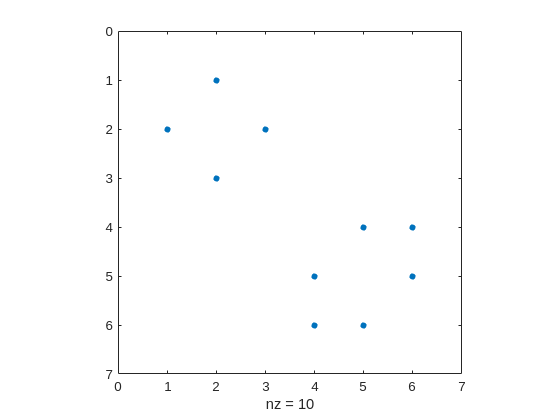


spy(A) %Visualizza la matrice di adiacenza;

deg=diag(sum(A)) %La degree matrix: ogni entry rappresenta il grado di un vertice

L=deg-A %La matrice lagrangiana


%il valore assoluto perché in una lagrangiana i valori sono di solito non-negativi
d=abs(eig(L)); 

disp(d)
J=find(d<1e-8); %Trova gli indici degli eigenvalue molto vicini allo zero
%Il num. di eigenvalue vicini allo zero rappresenta il num. di componenti connesse
numel(J) %Restituisce il numero di elementi nell'array

deg =      1     0     0     0     0     0
     0     2     0     0     0     0
     0     0     1     0     0     0
     0     0     0     2     0     0
     0     0     0     0     2     0
     0     0     0     0     0     2


L =      1    -1     0     0     0     0
    -1     2    -1     0     0     0
     0    -1     1     0     0     0
     0     0     0     2    -1    -1
     0     0     0    -1     2    -1
     0     0     0    -1    -1     2


    0.0000
    0.0000
    1.0000
    3.0000
    3.0000
    3.0000



     1
     2



ans = 2